# EH3DSB miniprojekt 2 – Frekvensanalyse af målte vibrationssignaler 

Team 4

202200284 - Danni Raetzel

201900368 - Martin Armose

### **Indledning og formål**

Formålet med denne rapport er at analysere vibrationssignaler optaget fra et accelerometer placeret ved et kugleleje i en havvindmølle. Signalet analyseres ved hjælp af diskret Fouriertransformation (DFT) i Matlab for at identificere frekvensindholdet og karakterisere de vigtigste signalparametre. Gennem forskellige signalbehandlingsteknikker vil frekvensspektret blive undersøgt for at få indsigt i de dominerende frekvenser samt energiforholdet i signalet.

**Indlæsning af data**

data = load('lydfil');

% Find signalet i strukturen 'data'
signal = data.raw_input / 100;  % Skalerer signalet fra enheder til volt

### Delopgaver

#### a

Plot de første 5 sekunder og beskriv hvilke frekvenser som I forventer signalet indeholder ud fra det tidslige plot (undersøg periodetiden). Tidsskalaen skal være i sekunder og amplitudeskalaen i volt

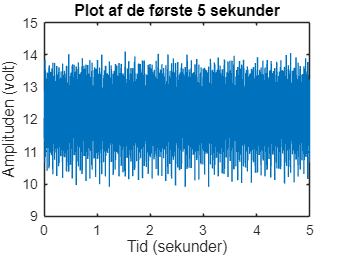

% Samplefrekvensen
Fs = 25600;  % Hz

% Tidssignal for de første 5 sekunder
t = (0:length(signal)-1)/Fs; % Beregn tidsvektor for hvert datapunkt i signalet
tdur = t(t <= 5);  % Vælg de første 5 sekunder
signal_5sek = signal(1:length(tdur));

% Plot signalet i tidsdomænet
figure;
plot(tdur, signal_5sek);
xlabel('Tid (sekunder)');
ylabel('Amplituden (volt)');
title('Plot af de første 5 sekunder');

**Forventede frekvenser:**

Vi zoomer ind på vores graf for at finde gentagelser eller mønstre som kan afsløre frekvenskombonenter i lydsignalet. Det første mønster vi finder kan ses på grafen herunder:

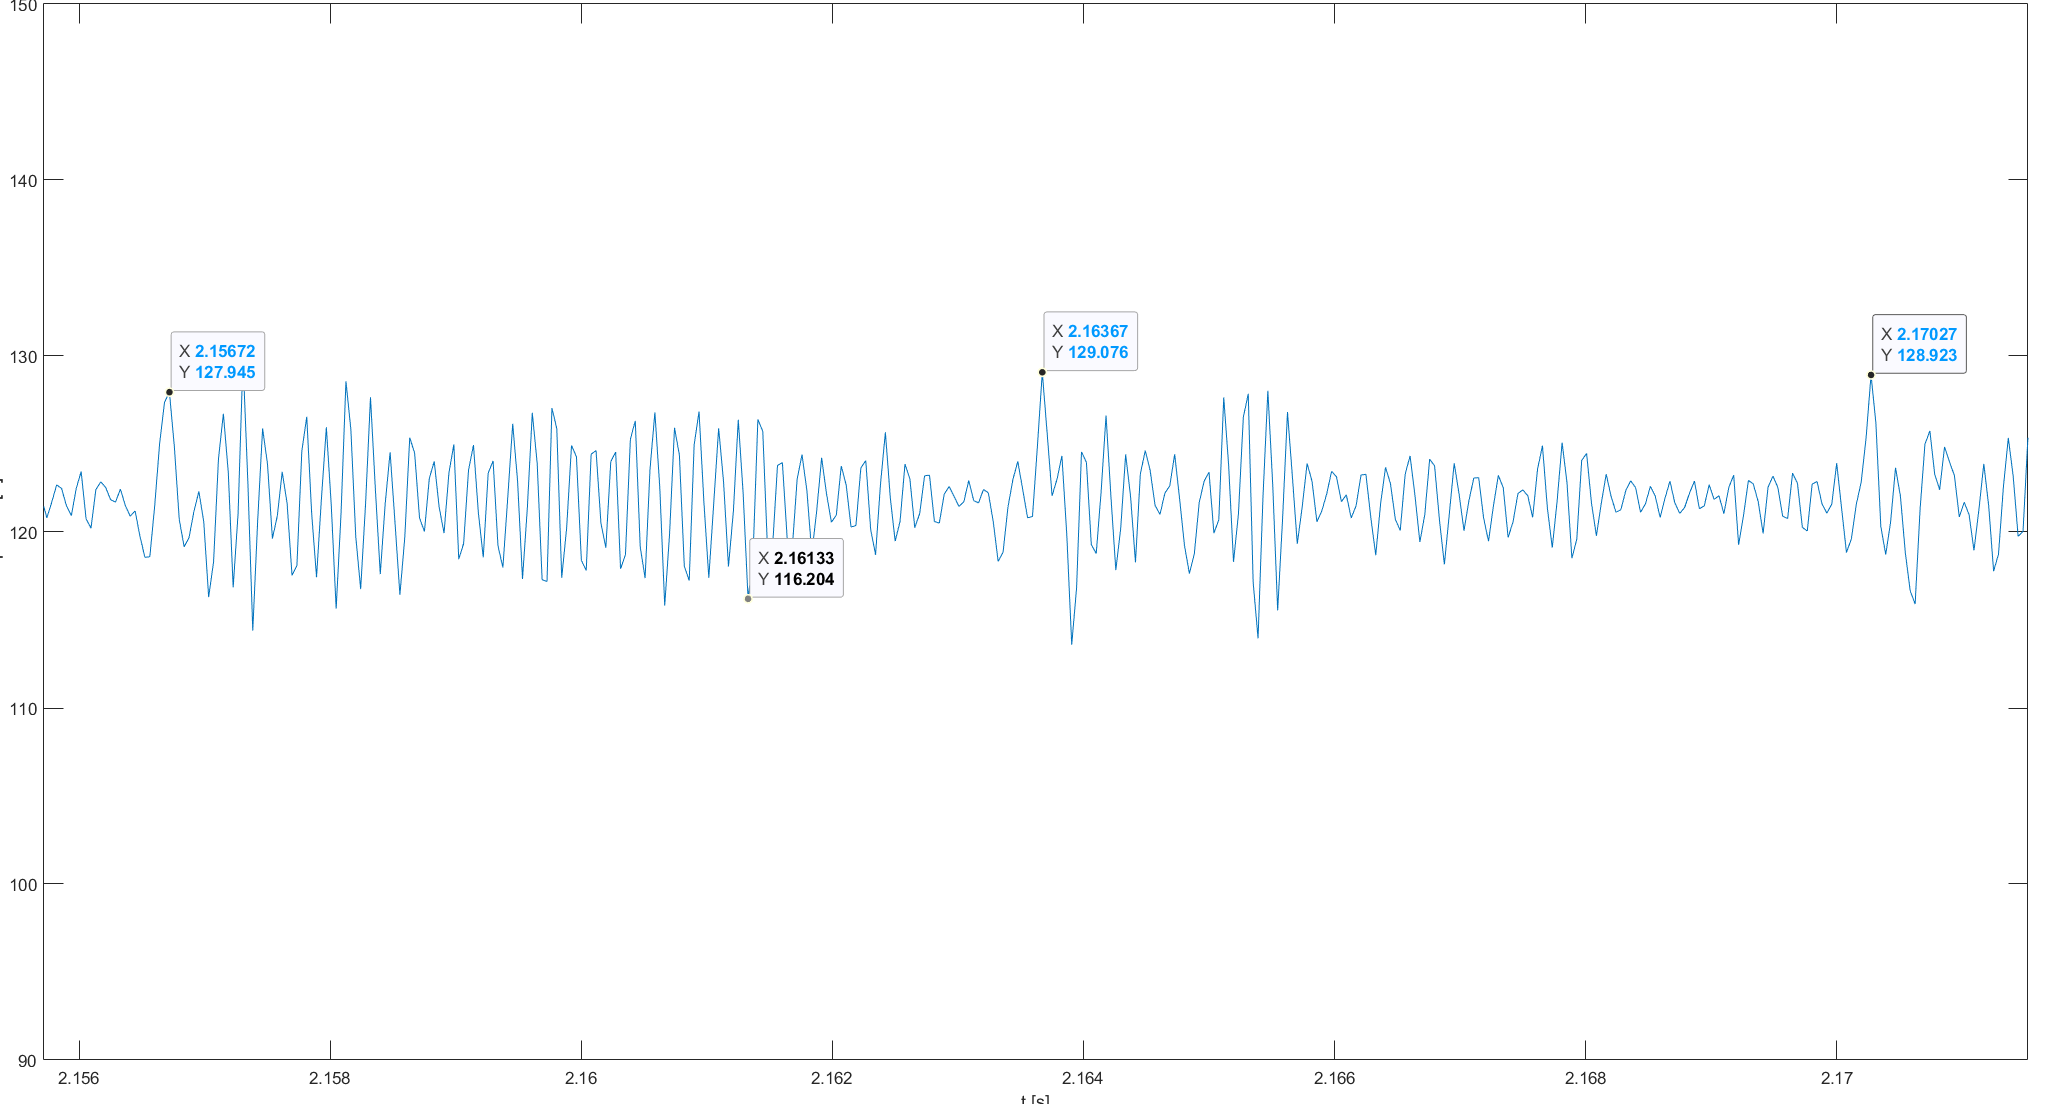

Vi beregner frekvensen:

x1 = 2.15672 % Første punkt der er markeret på grafen (Blå skrift)

x1 = 2.1567

x2 = 2.16367 % Andet punkt (Blå skrift)

x2 = 2.1637

dx1 = x2 - x1 % Forskel i tid

dx1 = 0.0070

f1 = 1/dx2 % En af frekvenskombonenterne vi forventer

f1 = 143.8849

Vi zoomer lidt ud på grafen og finder et mønster mere, som det ses på grafen herunder. 

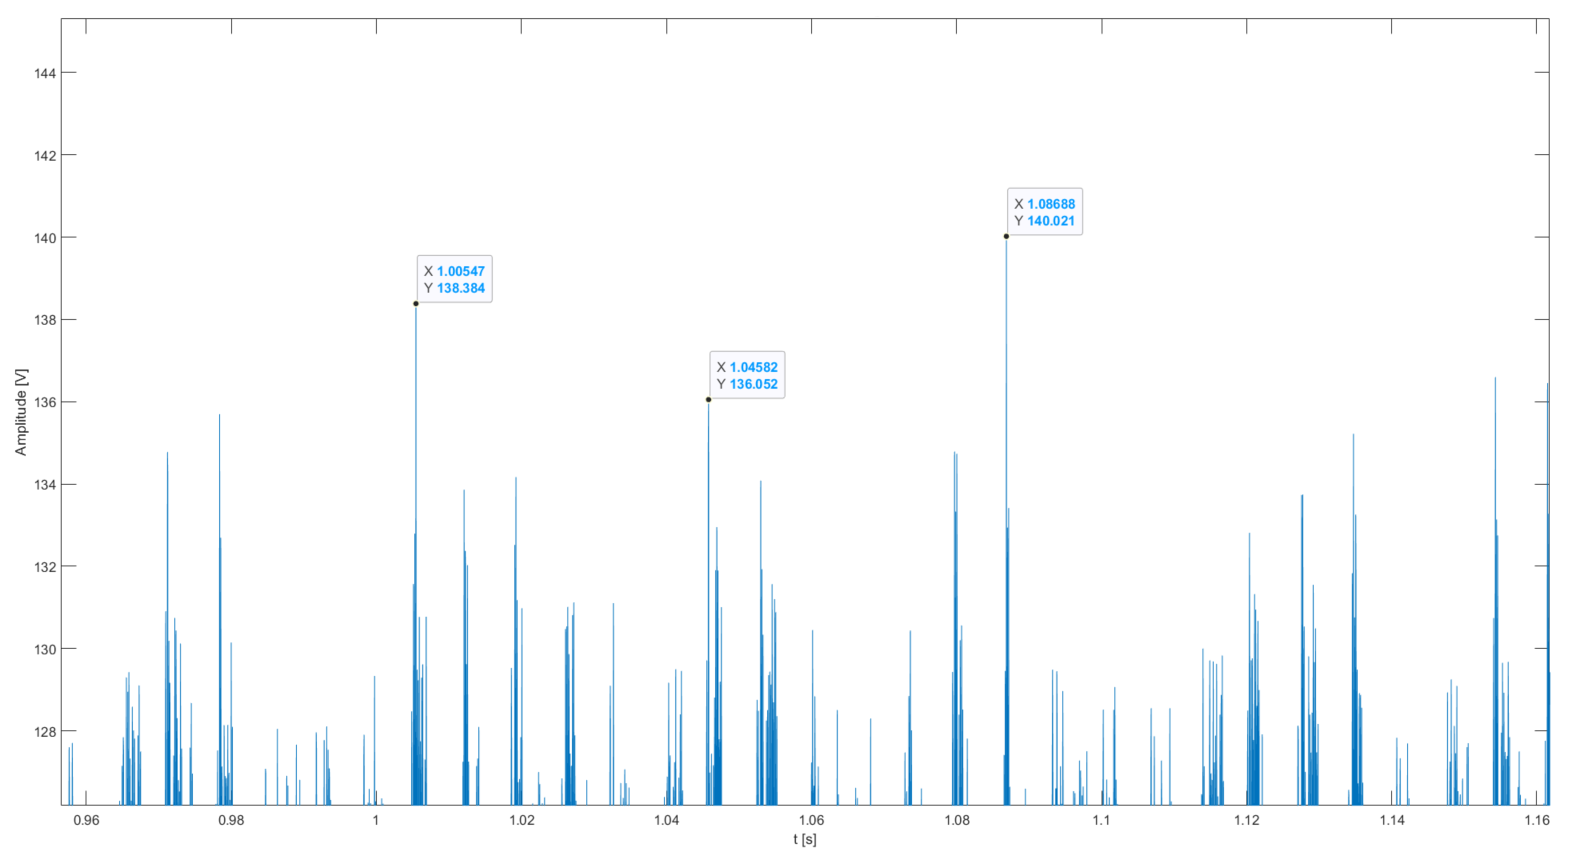

Der ses periodisk spikes i grafen. Når vi beregner frekvensen får vi frekvenskombonenten: 

x3 = 1.00547 % Første punkt der er markeret på grafen 

x3 = 1.0055

x4 = 1.04582 % Andet punkt 

x4 = 1.0458

dx = x4 - x3 % Forskel i tid

dx = 0.0403

f2 = 1/dx % En af frekvenskombonenterne vi forventer

f1 = 24.7831

Når vi sammenligner med frekvens komponenterne som vi har fundet senere i opgaven, kan vi se at vi ligger rimelig tæt på de 2 frekvenser vi har fundet frem til. Der er selvfølgelig mange flere frekvenskomponenter, men nu har vi fundet et kun meget lille uddrag som ses på grafen herunder

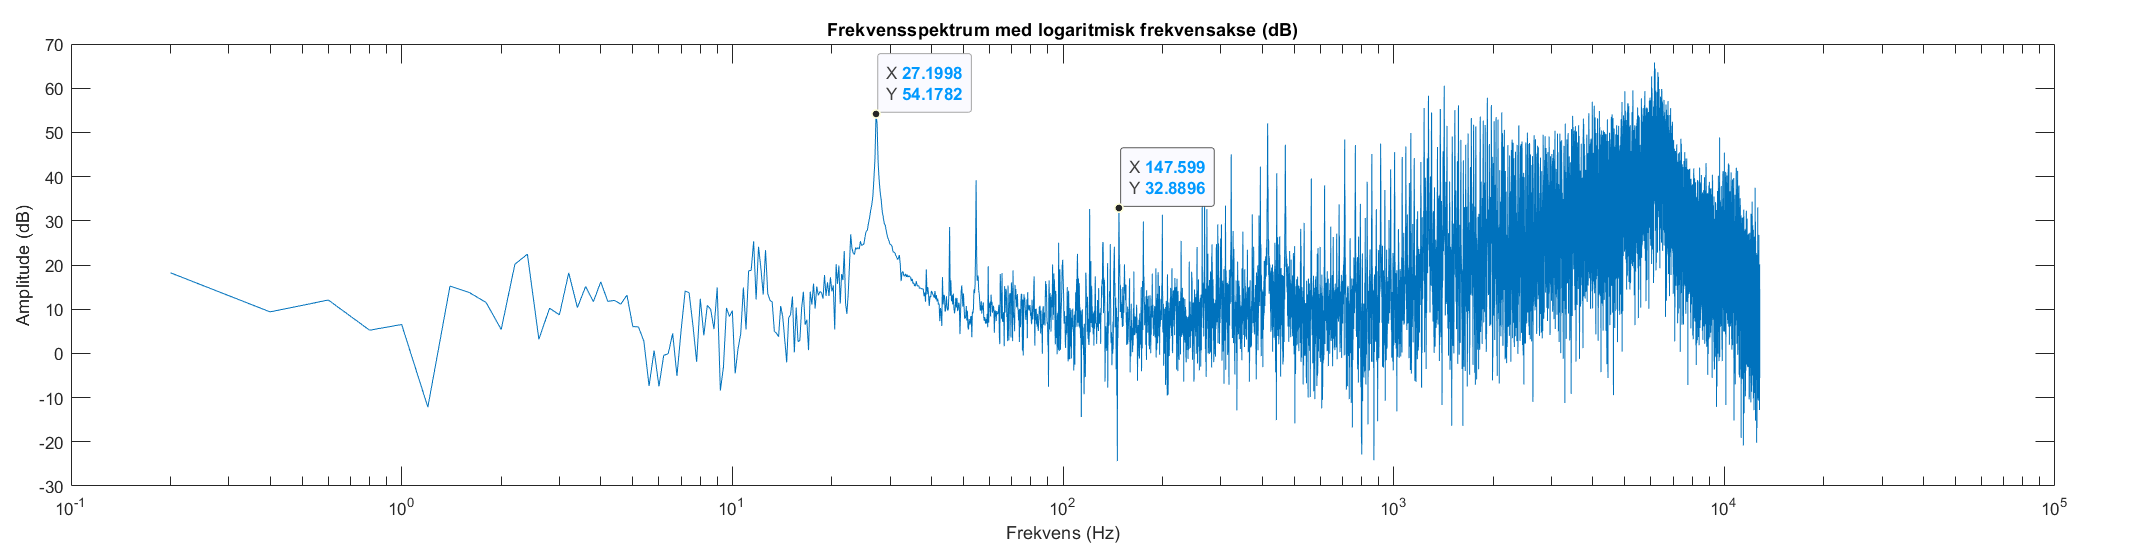

#### b

Beregn DC middelværdien, AC RMS-værdien, og energien for de første 5 sekunder af signalet.

dc_middel = mean(signal_5sek);       % DC Middelværdi
ac_signal = signal_5sek - dc_middel; % Fjerner DC Middelværdi fra signalet
ac_rms = rms(ac_signal);             % AC RMS-værdi
energi = sum(signal_5sek.^2);        % Energi i signalet

% Vis resultater
fprintf('DC-middelværdi: %.4f V\n', dc_middel);

DC-middelværdi: 12.1765 V


fprintf('AC RMS-værdi: %.4f V\n', ac_rms);

AC RMS-værdi: 0.3278 V


fprintf('Energien i signalet: %.1f V^2\n', energi);

Energien i signalet: 18992110.7 V^2


#### c

Træk DC middelværdien fra tidssignalet. Den stammer fra forsyningsspændingen og bærer ingen signalinformation (i dette tilfælde).

signal_ac = signal_5sek - dc_middel;  % Trækker DC middelværdi fra signalet

#### d

Lav frekvenstransformation på de første 5 sekunder af signalet og vis frekvensspektret

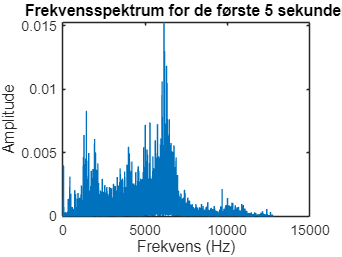

N = length(signal_ac);      % Antal samples for de første 5 sek
X = fft(ac_signal);         % FFT af AC-signalet

f = (0:N-1)*(Fs/N);         % Frekvensvektor
amplitude = abs(X)/N;       % Amplituden

% Plot frekvensspektret
figure;
plot(f(1:floor(N/2)), amplitude(1:floor(N/2)));  % floor funktion for at sikre heltal
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektrum for de første 5 sekunder');

#### e

Vis spektret både med logaritmisk og lineær frekvensakse (begge i Hz), samt størrelsen både i dB (i forhold til 1 volt) og i lineært mål (volt eller millivolt).

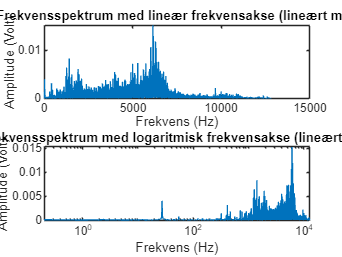

amplitude_dB = 20*log10(abs(X));   % Amplitude i dB

% Plot frekvensspektrum med lineær frekvensakse (lineært mål)
figure;
subplot(2,1,1);
plot(f(1:floor(N/2)), amplitude(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude (Volt)');
title('Frekvensspektrum med lineær frekvensakse (lineært mål)');

% Plot frekvensspektrum med logaritmisk frekvensakse (lineært mål)
subplot(2,1,2);
semilogx(f(1:floor(N/2)), amplitude(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude (Volt)');
title('Frekvensspektrum med logaritmisk frekvensakse (lineært mål)');

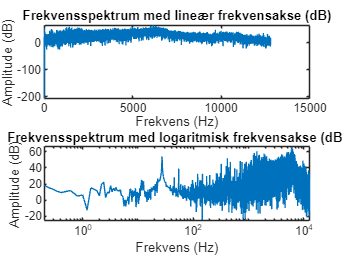


% Plot frekvensspektrum med lineær frekvensakse (dB mål)
figure;
subplot(2,1,1);
plot(f(1:floor(N/2)), amplitude_dB(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude (dB)');
title('Frekvensspektrum med lineær frekvensakse (dB)');

% Plot frekvensspektrum med logaritmisk frekvensakse (dB mål)
subplot(2,1,2);
semilogx(f(1:floor(N/2)), amplitude_dB(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude (dB)');
title('Frekvensspektrum med logaritmisk frekvensakse (dB)');

#### f

Diskutér, hvornår man bør benytte hvilken skala

- **Lineær frekvensakse:** Bruges når du analyserer et begrænset frekvensområde med jævnt fordelte frekvenser, især ved lavere frekvenser.

- **Logaritmisk frekvensakse:** Anvendes, når du vil se både lave og høje frekvenser i samme plot. Det komprimerer de højere frekvenser og gør det lettere at identificere detaljer i et bredt spektrum.

- **Lineær amplitudeskala:** Bruges, når du vil se de absolutte signalværdier. Nyttig ved store signalvariationer.

- **dB-skala:** Bruges, når du vil sammenligne frekvenskomponenters styrke over et stort dynamisk område eller for at fremhæve mindre frekvenser.

#### g

Hvad er den dominerende frekvens, og passer den med det forventede?

% Find den maksimale amplitude og dens indeks
[max_amplitude, index] = max(amplitude(1:floor(N/2)));  % Kun første halvdel af spektret

% Find den tilsvarende frekvens
dominerende_frekvens = f(index);

% Vis resultatet
fprintf('Den dominerende frekvens er %.1f Hz\n', dominerende_frekvens);

Den dominerende frekvens er 6146.75 Hz


Den dominerende passer ikke helt med det vi havde fundet frem til. Vi skulle have 'zoomet' mere ind på grafen for at have fundet den dominerende frekvens. Til gengæld fandt vi 2 andre frekvenskombonenterne som vist i opgave a.

#### h

Bestem lavfrekvent energi E_low (< 1000 Hz) og højfrekvent energi E_high (≥ 1000 Hz) for signalet. DC-værdien skal ikke tages med i disse beregninger.

% Lav frekvensgrænse på 1000 Hz
f_thresh = 1000;  % f_thresh: Frekvensgrænse

% Find indeks, der svarer til 1000 Hz
index_thresh = find(f >= f_thresh, 1);  % idx_thresh: Indeks ved 1000 Hz

% Beregn energien for lavfrekvent del (< 1000 Hz)
E_low = sum(amplitude(1:index_thresh).^2);  % E_low: Lavfrekvent energi

% Beregn energien for højfrekvent del (≥ 1000 Hz)
E_high = sum(amplitude(index_thresh+1:floor(N/2)).^2);  % E_high: Højfrekvent energi

% Vis resultaterne
fprintf('Lavfrekvent energi (E_low): %.4f V^2\n', E_low);

Lavfrekvent energi (E_low): 0.0001 V^2


fprintf('Højfrekvent energi (E_high): %.4f V^2\n', E_high);

Højfrekvent energi (E_high): 0.0536 V^2


#### i

Bestem energiforholdet Elow/Ehigh. Hvad betyder dette forhold?

% Beregn forholdet mellem lav- og højfrekvent energi
energy_ratio = E_low / E_high;

% Vis resultatet
fprintf('E_low / E_high: %.4f\n', energy_ratio);

E_low / E_high: 0.0027


Energiforholdet Elow / Ehigh viser, hvor stor en del af signalets energi er koncentreret i de lavere frekvenser i forhold til de højere frekvenser.

- **Forhold større end 1**: Indikerer, at størstedelen af energien er i de lave frekvenser, som typisk kommer fra langsomme mekaniske bevægelser (f.eks. vindmøllens rotation).

- **Forhold tæt på 1**: Betyder, at energien er ligeligt fordelt mellem lave og høje frekvenser.

- **Forhold mindre end 1**: Angiver, at der er mere energi i de højere frekvenser, hvilket kan signalere mekaniske problemer som slid eller resonanser.

#### j

Gang et Hanning-vindue på signalet og lav igen frekvenstransformation. Vis spektret. Gør vinduet nogen forskel i dette tilfælde? Hvorfor/hvorfor ikke?

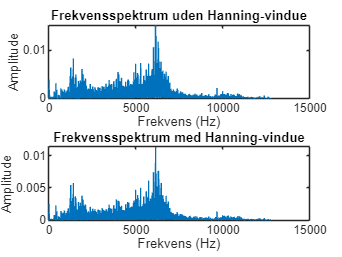

% Definer et Hanning-vindue for signalet
hanning_window = hann(length(signal_ac))';

% Multiplicer signalet med Hanning-vinduet
signal_hann = signal_ac .* hanning_window;

% Beregn FFT for det Hanning-vinduede signal
X_hann = fft(signal_hann);

% Beregn størrelsen af FFT'en (normaliseret)
amplitude_hann = abs(X_hann) / N;

% Plot det originale spektrum (uden vindue)
figure;
subplot(2, 1, 1);
plot(f(1:floor(N/2)), amplitude(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektrum uden Hanning-vindue');

% Plot spektret for det Hanning-vinduede signal
subplot(2, 1, 2);
plot(f(1:floor(N/2)), amplitude_hann(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektrum med Hanning-vindue');

**Gør Hanning-vinduet en forskel?**

- Hanning-vinduet gør ingen væsentlig forskel i dette tilfælde, da signalet er stabilt og ikke indeholder pludselige skift eller spektral lækage. Derfor er forskellen mellem frekvensspektret med og uden Hanning-vindue minimal.

#### k

Beregn igen AC RMS-værdien, og energien for de første 5 sekunder af signalet, nu med Hanningvinduet ganget på. Hvad gør Hanning vinduet ved disse værdier?

% Beregn AC RMS-værdien for Hanning-vinduet signal
ac_rms_hann = rms(signal_hann);

% Beregn energien for Hanning-vinduet signal
energi_hann = sum(signal_hann.^2);

% Vis resultaterne
fprintf('AC RMS-værdi med Hanning-vindue: %.4f V\n', ac_rms_hann);

AC RMS-værdi med Hanning-vindue: 0.1996 V


fprintf('Energi med Hanning-vindue: %.4f V^2\n', energi_hann);

Energi med Hanning-vindue: 5101.6657 V^2


Hanning-vinduet **reducerer både RMS-værdien og energien** i signalet, fordi det gradvist nedtoner signalets amplituder mod kanterne. Dette reducerer mængden af energi i signalet og den gennemsnitlige effekt (RMS), hvilket er hensigten med at bruge vinduet for at undgå spektral leakage.

#### l

Lav en udglatning/smoothing af signalet i frekvensdomænet og vis det resulterende spektrum på et plot. Diskuter hvornår det bør bruges, og hvad det gør ved den dominerende frekvens.

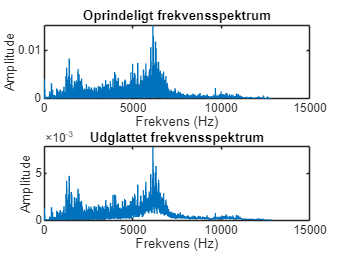

% Definer et glidende gennemsnit (smoothing) over amplituderne i frekvensdomænet
window_size = 10;  % Størrelse af vinduet til udglatning
smoothed_amplitude = movmean(amplitude(1:floor(N/2)), window_size);

% Plot det oprindelige frekvensspektrum
figure;
subplot(2,1,1);
plot(f(1:floor(N/2)), amplitude(1:floor(N/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Oprindeligt frekvensspektrum');

% Plot det udglattede frekvensspektrum
subplot(2,1,2);
plot(f(1:floor(N/2)), smoothed_amplitude);
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Udglattet frekvensspektrum');

**Hvornår bør udglatning bruges?**

- Udglatning bør bruges, når spektret indeholder meget støj, og det er svært at identificere de vigtige frekvenskomponenter.

- Det er særlig nyttigt, når du vil fokusere på de **dominerende frekvenser** og filtrere mindre støjende frekvenser væk.

**Hvad gør udglatning ved den dominerende frekvens?**

- Udglatning bør **ikke påvirke den dominerende frekvens**, hvis vinduet er passende. Den dominerende frekvens vil stadig være den med størst amplitude.

- Hvis vinduet er for stort, kan udglatning dog skjule vigtige frekvensdetaljer og gøre det sværere at opdage skarpe frekvenskomponenter, hvilket kan føre til en fejlagtig analyse af den dominerende frekvens.

### Konklusion

Gennem denne analyse af vibrationssignaler fra en havvindmølle blev frekvensindholdet identificeret ved hjælp af diskret Fouriertransformation (DFT). De vigtigste signalparametre, såsom DC-middelværdi, AC RMS-værdi og energiforhold, blev beregnet, og det blev påvist, at de lavere frekvenser dominerede signalets energi, hvilket stemmer overens med forventningerne om mekaniske vibrationer fra vindmøllens rotation.

Ved at anvende et Hanning-vindue kunne spektral lækage reduceres, selvom det i dette tilfælde kun havde en minimal effekt, da signalet var stabilt. Udglatning af frekvensspektret hjalp med at reducere støj og gjorde det lettere at identificere de dominerende frekvenser uden at påvirke deres amplitude væsentligt. Samlet set blev signalets frekvensindhold og energiforhold tydeliggjort gennem brugen af forskellige signalbehandlingsteknikker, hvilket giver indsigt i vindmøllens mekaniske sundhed.